## Q4-b

% Parameters
alpha1 = 3;
N = 500;
R = 400;
lambda_X = 1; % variance of epsilon_x
lambda_Y = 1; % variance of epsilon_y

% Storage for results
alpha1_LS = zeros(R, 1);
alpha1_Alternate = zeros(R, 1);

for r = 1:R
    % Generate true data
    X_star = randn(N, 1); % X_star with mean 0 and variance 1
    Y_star = alpha1 * X_star;
    
    % Generate corrupted observations
    epsilon_x = sqrt(lambda_X) * randn(N, 1);
    epsilon_y = sqrt(lambda_Y) * randn(N, 1);
    X = X_star + epsilon_x;
    Y = Y_star + epsilon_y;
    
    % LS Estimator
    alpha1_LS(r) = (X' * Y) / (X' * X);
    
    % Alternate Estimator
    % Define the objective function for Alternate
    fun = @(a) sum((X_star - X).^2 + (a * X_star - Y).^2);
    % Solve the optimization problem
    alpha1_Alternate(r) = fminunc(fun, alpha1);
end

% Calculate biases
bias_LS = mean(alpha1_LS) - alpha1;
bias_Alternate = mean(alpha1_Alternate) - alpha1;

% Round off the biases to determine if they are unbiased
bias_LS_rounded = round(bias_LS, 2);
bias_Alternate_rounded = round(bias_Alternate, 2);

% Display results
fprintf('LS Estimator Bias: %.4f (Rounded: %.4f)\n', bias_LS, bias_LS_rounded);

LS Estimator Bias: -1.5005 (Rounded: -1.5000)


fprintf('Alternate Estimator Bias: %.4f (Rounded: %.4f)\n', bias_Alternate, bias_Alternate_rounded);

Alternate Estimator Bias: 0.0006 (Rounded: 0.0000)


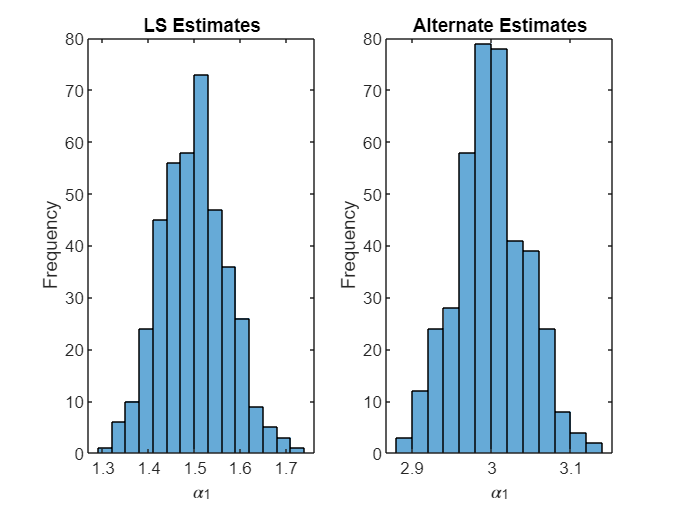


% Plot histograms of the estimates
figure;
subplot(1, 2, 1);
histogram(alpha1_LS);
title('LS Estimates');
xlabel('\alpha_1');
ylabel('Frequency');

subplot(1, 2, 2);
histogram(alpha1_Alternate);
title('Alternate Estimates');
xlabel('\alpha_1');
ylabel('Frequency');